% Convert the dat by NT_Convert_V0 
load 1.Halfanode_Cell22_Formation.mat  % load the raw data  

% Anode material: MNO (NbMo12O33)

F = 96485.33212; % C/mol, Faraday constant
m_Graphite = 17.6/1000; % mass loading of active anode material in mg/1000 = [g]
M_LixC=72; % molar mass of LiC6
Vol_F=0.676756; % Volume fraction of active material 
Th_a=65/1000000; % Thickness of materials layer in [m]
GSM_a=99.4155*1.03; % area mass of active material layer in [g/m^2]
d = 1.5; % diameter of the electrode in cm
A = pi*(d/2)^2; % surface area of electrode in cm^2

x =1.0000% set the expansion factor for the anode in mAh/cm^2.

x = 1

y=1.2% This is more the target areal capacity than the expansion factor though

y = 1.2000

% For instance, target capacity for anode is 1.1 mAh/cm2 if we want
% capacity of cathode to be 1.0 mAh/cm2 with a full-cell NP ratio of 1.1.


**Section1: Obtain the Voltage vs. Capacity for first and second cycles, and apply the expansion factor. Interpolation.**

% To get the data for the 1st cycle
data.cycle_number;  % load the data for cycle number
k = find(data.cycle_number==0 & data.ave_I_mA<0); % To find the first discharge
l = find(data.cycle_number==1 & data.ave_I_mA>0); % To find the first charge
Voldch_a = data.Ecell_V(k); % obtain the voltage in the first discharge
Volch_a = data.Ecell_V(l); % obtain the voltage in the first charge
Capdch_a = data.Capacity_mAh(k)/A; % to have the 1st charge capacity in [mAh/cm^2]
Capch_a = data.Capacity_mAh(l)/A; % to have the 1st discharge capacity in [mAh/cm^2]
disp('Max capacity on 1st cycle charge and discharge in mAh/cm2')

Max capacity on 1st cycle charge and discharge in mAh/cm2



[MCapdch,idxCapdch] = max(Capdch_a) % to get the maximal capacity in 1st charge

MCapdch = 3.7624

idxCapdch = 2064

[MCapch,idxCapch] = max(Capch_a) % to get the maximal capacity in 1st discharge

MCapch = 3.4918

idxCapch = 1466

ExpCapdch = Capdch_a*x/MCapdch % to obtain the expanded capacity during 1st discharge

ExpCapdch =     0.0022
    0.0216
    0.0647
    0.1142
    0.1638
    0.2155
    0.2673
    0.3190
    0.3729
    0.4246


ExpCapch = Capch_a*x/MCapdch % to obtain the expanded capacity during 1st charge

ExpCapch =     0.0000
    0.0007
    0.0013
    0.0020
    0.0026
    0.0033
    0.0040
    0.0046
    0.0053
    0.0059


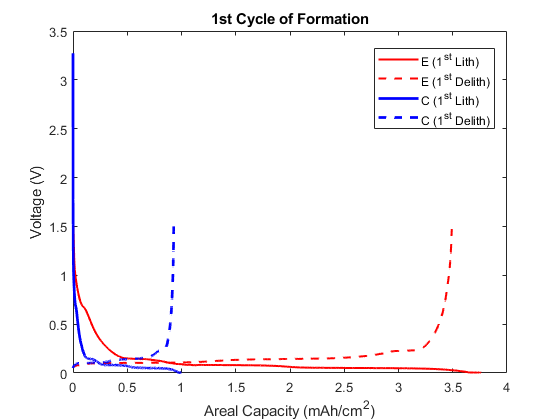


plot(Capdch_a,Voldch_a,'r-','linewidth',1.5)
hold on
plot(Capch_a,Volch_a,'r--','linewidth',1.5)
plot(ExpCapdch,Voldch_a,'b-','linewidth',2) % plot the V vs.capacity(expanded) during during 1st discharge 
hold on 
plot(ExpCapch,Volch_a,'b--','linewidth',2) % plot the V vs.capacity(expanded) during during 1st charge 

title('1st Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('E (1^s^t Lith)','E (1^s^t Delith)','C (1^s^t Lith)','C (1^s^t Delith)','Location',"best")
hold off


% to get the data for the 2nd cycle
secondk = find(data.cycle_number==1 & data.ave_I_mA<0 ); % obtain the index for the second discharge
secondl = find(data.cycle_number==2 & data.ave_I_mA>0); % To find the first charge
secondVoldch_a = data.Ecell_V(secondk(2:end)); % obtain the voltage in the first discharge
secondVolch_a = data.Ecell_V(secondl); % obtain the voltage in the first charge
secondCapdch_a = data.Capacity_mAh(secondk(2:end))/A;
secondCapch_a = data.Capacity_mAh(secondl)/A;
disp('Max capacity on 2nd cycle charge and discharge in mAh/cm2')

Max capacity on 2nd cycle charge and discharge in mAh/cm2


[M2ndCapdch,idx2ndCapdch] = max(secondCapdch_a)

M2ndCapdch = 3.5349

idx2ndCapdch = 1569

[M2ndCapch,idx2ndCapch] = max(secondCapch_a)

M2ndCapch = 3.5311

idx2ndCapch = 1483

ExpCap2nddch = secondCapdch_a*x/M2ndCapch % to obtain the expanded capacity during 2nd discharge

ExpCap2nddch =     0.0013
    0.0051
    0.0147
    0.0326
    0.0561
    0.0843
    0.1170
    0.1542
    0.1957
    0.2392


ExpCap2ndch = secondCapch_a*x/M2ndCapch % to obtain the expanded capacity during 2nd charge

ExpCap2ndch =     0.0000
    0.0003
    0.0010
    0.0017
    0.0024
    0.0031
    0.0038
    0.0045
    0.0052
    0.0059


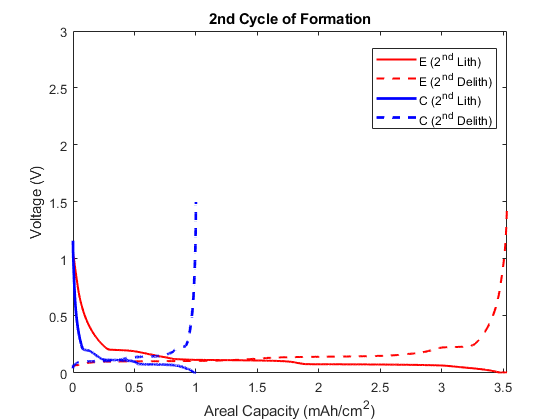


plot(secondCapdch_a,secondVoldch_a,'r-','linewidth',1.5)
hold on
plot(secondCapch_a,secondVolch_a,'r--','linewidth',1.5)
plot(ExpCap2nddch,secondVoldch_a,'b-','linewidth',2) % plot the V vs.capacity(expanded) during during 2nd discharge
plot(ExpCap2ndch,secondVolch_a,'b--','linewidth',2) % plot the V vs.capacity(expanded) during during 2nd charge

title('2nd Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('E (2^n^d Lith)','E (2^n^d Delith)','C (2^n^d Lith)','C (2^n^d Delith)','Location',"best")
hold off
axis tight

xlim([0.00 3.53])
ylim([0.00 3.0])


% to get the voltage and capacity raw data for first and second cycle
Data_1st_dch=[Capdch_a,Voldch_a];
Data_1st_ch=[Capch_a,Volch_a];
Data_2nd_dch=[secondCapdch_a,secondVoldch_a];
Data_2nd_ch=[secondCapch_a,secondVolch_a];
Header_Data_1st_dch = {'1_Li_Cap','1_Li_V'};
Header_Data_1st_ch = {'1_Deli_Cap','1_Deli_V'};
Header_Data_2nd_dch = {'2_Li_Cap','2_Li_V'};
Header_Data_2nd_ch = {'2_Deli_Cap','2_Deli_V'};
Data_VvsCap.Data_1st_dch=[Header_Data_1st_dch;num2cell(Data_1st_dch)];
Data_VvsCap.Data_1st_ch=[Header_Data_1st_ch;num2cell(Data_1st_ch)];
Data_VvsCap.Data_2nd_dch=[Header_Data_2nd_dch;num2cell(Data_2nd_dch)];
Data_VvsCap.Data_2nd_ch=[Header_Data_2nd_ch;num2cell(Data_2nd_ch)];

% Create interp1 function for 1st and 2nd cycles
% use the second cycle
disp('get interpolated values for voltage at different capacities for 1st cycle')

get interpolated values for voltage at different capacities for 1st cycle


Z = 100;
% disp('get interpolated values for voltage at different capacities for 2nd cycle')

A1_m=C1_m; % to find the first section of A1_m
A1_n = C1_n;% to find the second section of A1_n
A_Vxpdch = interp1(ExpCapdch,Voldch_a,A1_m,'linear','extrap'); % to interpolate the voltage for first section of A1m 
A_Vxpch = interp1(ExpCapch,Volch_a,A1_n,'linear')% to interpolate the voltage for second section of A1n 

A_Vxpch =        NaN
    0.0758
    0.0816
    0.0884
    0.0934
    0.0968
    0.0988
    0.1001
    0.1010
    0.1015


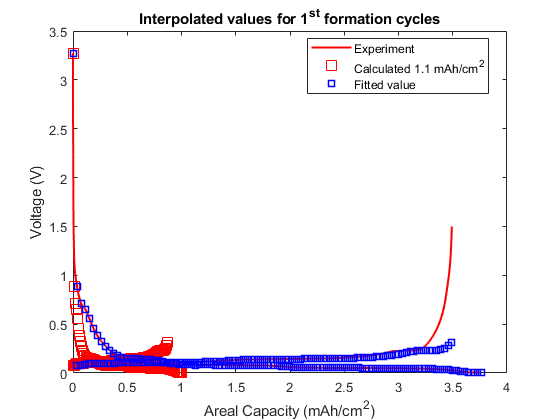


g1=plot(Capdch_a,Voldch_a,'r-','linewidth',1.5);
hold on
g2=plot(Capch_a,Volch_a,'r-','linewidth',1.5);
g3=plot(A1_m,A_Vxpdch,'rs','MarkerSize',10);
g4=plot(A1_n,A_Vxpch,'rs','MarkerSize',10);
g5=plot(A1_m*MCapdch/max(A1_m),A_Vxpdch,'bs','linewidth',1.5);
g6=plot(A1_n*MCapch/max(A1_n),A_Vxpch,'bs','linewidth',1.5);
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend([g1,g3,g5],'Experiment','Calculated 1.1 mAh/cm^2','Fitted value','location',"best")
title('Interpolated values for 1^s^t formation cycles')
hold off


save A1_m;
save A1_n;
save A_Vxpdch;
save A_Vxpch;

% use the second cycle
disp('get interpolated values for voltage at different capacities for 2nd cycle')

get interpolated values for voltage at different capacities for 2nd cycle


Z = 100;
% disp('get interpolated values for voltage at different capacities for 2nd cycle')
A2_m=C2_m % to find the first section of A1_m

A2_m =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


A2_n = C2_n% to find the second section of A1_n

A2_n =          0
    0.0095
    0.0191
    0.0286
    0.0382
    0.0477
    0.0573
    0.0668
    0.0764
    0.0859


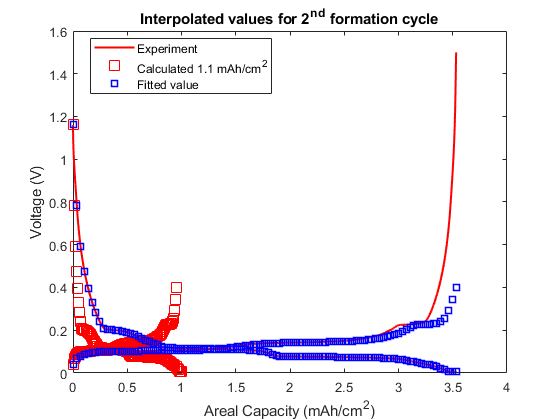

A_Vxp2nddch = interp1(ExpCap2nddch,secondVoldch_a,A2_m,'linear','extrap'); % to interpolate the voltage for first section of A1m 
A_Vxp2ndch = interp1(ExpCap2ndch,secondVolch_a,A2_n,'linear','extrap');% to interpolate the voltage for second section of A1n 

g1=plot(secondCapdch_a,secondVoldch_a,'r-','linewidth',1.5);
hold on
g2=plot(secondCapch_a,secondVolch_a,'r-','linewidth',1.5);
g3=plot(A2_m,A_Vxp2nddch,'rs','MarkerSize',10);
g4=plot(A2_n,A_Vxp2ndch,'rs','MarkerSize',10);
g5=plot(A2_m*M2ndCapch/max(A2_m),A_Vxp2nddch,'bs','linewidth',1.5);
g6=plot(A2_n*M2ndCapch/max(A2_n),A_Vxp2ndch,'bs','linewidth',1.5);
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend([g1,g3,g5],'Experiment','Calculated 1.1 mAh/cm^2','Fitted value','location',"best")
title('Interpolated values for 2^n^d formation cycle')
hold off


save A2_m;
save A2_n;
save A_Vxp2nddch;
save A_Vxp2ndch;


**Section 2: Obtain the Stoichiometry**

disp 'The stochoimetry method from YX'

The stochoimetry method from YX


cCp= max(Capdch_a);  % mAh/g, practical capacity of NMO, 
% nMNO = 0.0064/M_MNO; % mol, the overall mol of MNO 
%nLi=cCp*A*3.6/F  % mol, the overall mole of lithium in anode
nLi=(99.4155/10000)*A/M_LixC

nLi = 2.4400e-04

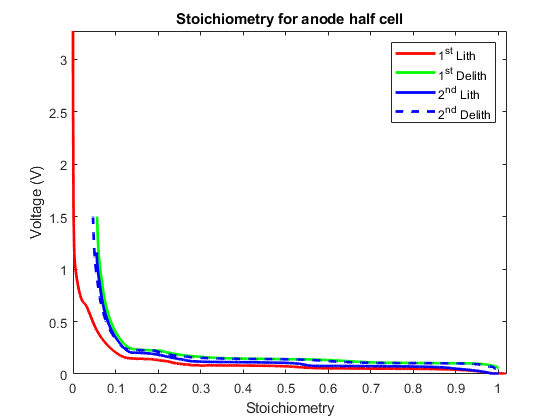


% to calculate the transfered lithium during first and second cycles
ntrans_Li_dch = Capdch_a*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the first discharge
ntrans_Li_ch = Capch_a*A*3.6/F; % n=cap*area*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the first charge
ntrans_Li_2nddch = secondCapdch_a*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the second discharge
ntrans_Li_2ndch = secondCapch_a*A*3.6/F; % n=cap*3.6/F(C/mol)=mol,calcuate the transfer of lithium in the second charge
nmax=max(ntrans_Li_dch);

% to calculate the remaining lithium during first and second cycles
 % n_remain_Li_dch = nlithium-ntrans_Li_dch;  % remaining lithium in the first discharge
 n_remain_Li_ch = nLi-ntrans_Li_ch;  % remaining lithium in the first charge
 n_remain_Li_2nddch = nLi-ntrans_Li_2nddch; % remaining lithium in the second discharge
 n_remain_Li_2ndch = max(n_remain_Li_2nddch)-ntrans_Li_2ndch; % remaining lithium in the second charge

% to calcuate the stoichiometry of cathode during first and second cycle
Sto_Li_dch = ntrans_Li_dch/nLi; % stoichiometry change during the first dischagre
Sto_Li_ch = n_remain_Li_ch/nLi; % stoichiometry change during the first chagre
Sto_Li_2nddch = (min(Sto_Li_ch)+ntrans_Li_2nddch/nLi)/1.01; % stoichiometry change during the 2nd dischagre
Sto_Li_2ndch =(max(Sto_Li_2nddch)-ntrans_Li_2ndch/nLi)/1.01; % stoichiometry change during the 2nd chagre

% to plot the Voltage vs. Stoichiometry druing the first and second cycles
plot(Sto_Li_dch,Voldch_a,'r-','linewidth',2)
set(gca,'xDir','normal')
hold on
plot(Sto_Li_ch,Volch_a,'g-','linewidth',2)
% set(gca,'xDir','reverse')
hold on
% add the Voltage vs. Stoichiometry druing the second cycle
plot(Sto_Li_2nddch,secondVoldch_a,'b-','linewidth',2)
set(gca,'xDir','normal')
hold on
plot(Sto_Li_2ndch,secondVolch_a,'b--','linewidth',2)
legend('1^s^t Lith','1^s^t Delith','2^n^d Lith','2^n^d Delith','location','northeast')
xlabel('Stoichiometry')
ylabel('Voltage (V)')
title('Stoichiometry for anode half cell')
hold off
xlim([0.000 1.02])
ylim([0.00 3.27])


Sa_Vxp2ndch = interp1(ExpCap2nddch,Sto_Li_2nddch,A2_m,'linear','extrap');
Sa_Vxp2nddch = interp1(ExpCap2ndch,Sto_Li_2ndch,A2_n,'linear','extrap');
save Sa_Vxp2ndch;
save Sa_Vxp2nddch;

disp 'The stochoimetry method from Emma'

The stochoimetry method from Emma


% Sto=C(mol/m^3)*Vol_F(active material)*Thickness(m)*M_NMC(g/mol)/GSM(g/m^2)
% C=Cap(mAh)*3.6/A(m^2)/F/Thickness
Csmax_Li=31388.89 % the theroical maximl lithium concentration in particle

Csmax_Li = 3.1389e+04

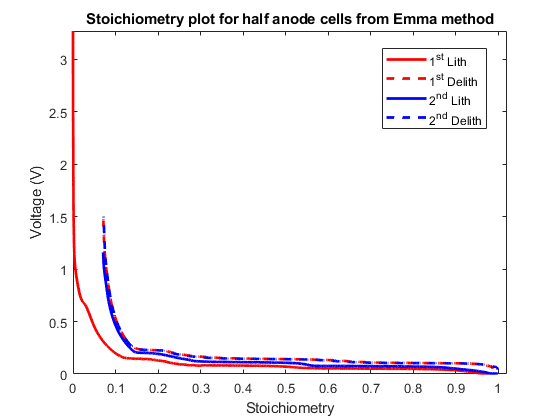

Q1dch=abs(data.Q_Qo_mAh(k));
Q1ch=abs(data.Q_Qo_mAh(l));
Q2dch=abs(data.Q_Qo_mAh(secondk));
Q2ch=abs(data.Q_Qo_mAh(secondl));

C1dch=(Q1dch/(A/10000))*3.6/F/Th_a/Vol_F;
C1ch=(Q1ch/(A/10000))*3.6/F/Th_a/Vol_F;
C2dch=(Q2dch/(A/10000))*3.6/F/Th_a/Vol_F;
C2ch=(Q2ch/(A/10000))*3.6/F/Th_a/Vol_F;

Sto_Li_dch_E=(C1dch)*Vol_F*Th_a*M_LixC/GSM_a;
Sto_Li_ch_E=(C1ch)*Vol_F*Th_a*M_LixC/GSM_a;
Sto_Li_2dch_E=(C2dch)*Vol_F*Th_a*M_LixC/GSM_a;
Sto_Li_2ch_E=(C2ch)*Vol_F*Th_a*M_LixC/GSM_a;

plot(Sto_Li_dch_E,Voldch_a,'r-','linewidth',2)
%set(gca,'xDir','reverse')
hold on
plot(Sto_Li_ch_E,Volch_a,'r--','linewidth',2)
hold on
% add the Voltage vs. Stoichiometry plot for the second cycle
plot(Sto_Li_2dch_E(2:end),secondVoldch_a,'b-','linewidth',2)
% set(gca,'xDir','reverse')
hold on
plot(Sto_Li_2ch_E(1:end),secondVolch_a,'b--','linewidth',2)
% ax= xDir:'reverse' YDir:'reverse'
legend('1^s^t Lith','1^s^t Delith','2^n^d Lith','2^n^d Delith','location',"best")
xlabel('Stoichiometry')
ylabel('Voltage (V)')
title('Stoichiometry plot for half anode cells from Emma method')
hold off
axis tight

xlim([0.000 1.02])
ylim([0.00 3.27])

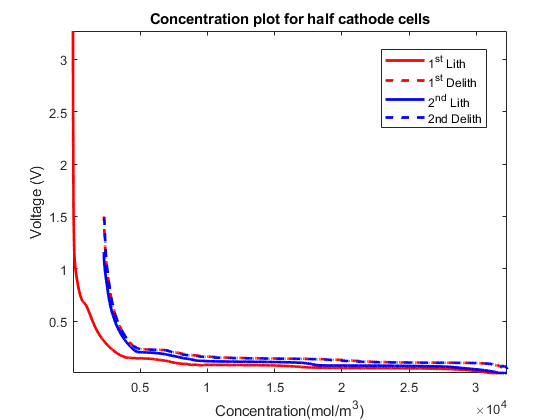


% to plot the voltage with concentration in the particle
plot(C1dch,Voldch_a,'r-','linewidth',2)
%set(gca,'xDir','reverse')
hold on
plot(C1ch,Volch_a,'r--','linewidth',2)
hold on
% add the Voltage vs. Stoichiometry plot for the second cycle
plot(C2dch(2:end),secondVoldch_a,'b-','linewidth',2)
%set(gca,'xDir','reverse')
hold on
plot(C2ch,secondVolch_a,'b--','linewidth',2)
% ax= xDir:'reverse' YDir:'reverse'
legend('1^s^t Lith','1^s^t Delith','2^n^d Lith','2nd Delith','location',"best")
xlabel('Concentration(mol/m^3)')
ylabel('Voltage (V)')
title('Concentration plot for half cathode cells')
hold off
ylim([2.5 4.3])
axis tight

**Section 4: plot dQ/dV (adjusted with expansion factor)**


% To calculate dV and dQ in the second cycle
% To calculate dV and dQ in the second cycle

%Function for DVA and ICA to make the data smooth

MA = 25;  % span for moving average filter

% g = gausswin(100);  % 100 is the sample size for the gaussian window

% g value determines the width of the smoothing window.
%  If you have signal process toolbox uncomment above else use the expressions below, 

%%%%%%%%%%%%%%%%%%%%%%%% Use this fitted gausswin if you don't have signal processing
%%%%%%%%%%%%%%%%%%%%%%%% toolbox. Here using the fitted value
%  of gausswin for 100 sample size, for different sample size, fit and
%  change the value of alpha.

N=100;
M= (N-1)/2;
alpha=2.5;
n= (-(N-1)/2:(N-1)/2)';
g= exp((-0.5)*((alpha^2 *n.^2)/(M^2)));
g = g/sum(g);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% to obtain the second cycle without the interpolation
B = 1:(size(secondVoldch_a)-1);
deltaVm2nddch = secondVoldch_a(B+1)-secondVoldch_a(B);
deltaCapm2nddch = A*x*(secondCapdch_a(B+1)-secondCapdch_a(B));
% DiffQV2nddch = deltaCapm2nddch./deltaVm2nddch;
DiffQV2nddch = smooth(deltaCapm2nddch)./smooth(deltaVm2nddch);
Q=find(DiffQV2nddch<0)

Q =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


DiffQV2nddch=DiffQV2nddch(Q)

DiffQV2nddch = 	1.0e+18 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


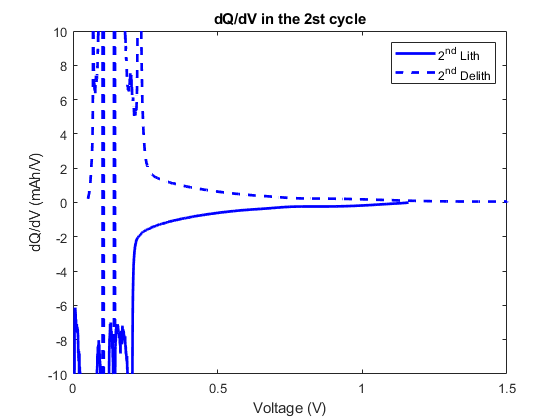

plot(secondVoldch_a(Q),DiffQV2nddch,'b-','linewidth',2)
set(gca,'xDir','normal')
hold on
% To obtain the first discharge
C = 1:(size(secondVolch_a)-1);
deltaVm2ndch = secondVolch_a(C+1)-secondVolch_a(C);
deltaCapm2ndch = A*x*(secondCapch_a(C+1)-secondCapch_a(C));
% To plot the dQ/dV in the first cycle
%plot(secondVolch_a(2:end),deltaCapm2ndch./deltaVm2ndch,'b--','linewidth',2);
plot(secondVolch_a(2:end),smooth(deltaCapm2ndch)./smooth(deltaVm2ndch),'b--','linewidth',2);

xlabel('Voltage (V)')
ylabel('dQ/dV (mAh/V)')
legend('2^n^d Lith','2^n^d Delith')
title('dQ/dV in the 2st cycle')
hold off
xlim([0 1.5])
ylim([-10 10])

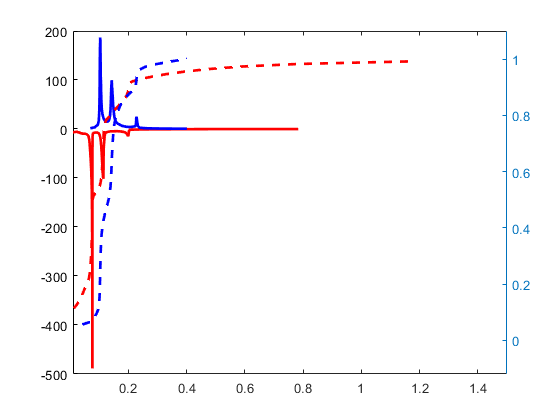


% to plot the dQ/dV from the interpolation and also the stochoimetry for
% the whole votage in second cycle
plot(A_Vxp2nddch(2:end),(M2ndCapdch/max(A2_m))*smooth(diff(A2_m))./smooth(diff(A_Vxp2nddch)),'r-','linewidth',2)
hold on
plot(A_Vxp2ndch(2:end),(M2ndCapch/max(A2_n))*smooth(diff(A2_n))./smooth(diff(A_Vxp2ndch)),'b-','linewidth',2)
yyaxis right
plot(A_Vxp2nddch,Sa_Vxp2nddch,'r--','linewidth',2)
plot(A_Vxp2ndch,Sa_Vxp2ndch,'b--','linewidth',2)
hold off
xlim([0.01 1.50])
ylim([-0.12 1.1])
hold off

Data_anode=[A_Vxp2nddch,Sa_Vxp2nddch,A_Vxp2ndch,Sa_Vxp2ndch];
Header_Data_anode = {'V at lithiation / V','Stochoimetry at lithiation','V at delithiation / V','Stochoimetry at delithiation'};
Data_anode=[Header_Data_anode;num2cell(Data_anode)]

Data_anode = 102×4 cell array
    {'V at lithiation / V'}    {'Stochoimetry at lithiation'}    {'V at delithiation / V'}    {'Stochoimetry at delithiation'}
    {[             1.1614]}    {[                    0.9917]}    {[               0.0418]}    {[                      0.0559]}
    {[             0.7835]}    {[                    0.9827]}    {[               0.0694]}    {[                      0.0653]}
    {[             0.5908]}    {[                    0.9737]}    {[               0.0762]}    {[                      0.0748]}
    {[             0.4751]}    {[                    0.9647]}    {[               0.0844]}    {[                      0.0842]}
    {[             0.3934]}    {[                    0.9556]}    {[               0.0903]}    {[                      0.0937]}
    {[             0.3309]}    {[                    0.9466]}    {[               0.0943]}    {[                      0.1031]}
    {[             0.2808]}    {[                    0.9376]}    {[              

[p S Mu] = polyfit(Sa_Vxp2nddch,A_Vxp2nddch,6)

f=polyval(p,Sa_Vxp2nddch)

T = table(Sa_Vxp2nddch,A_Vxp2nddch,f,A_Vxp2nddch-f,'VariableNames',{'X','Y','Fit','FitError'})

plot(Sa_Vxp2nddch,A_Vxp2nddch)

hold on

plot(Sa_Vxp2nddch,f)

hold off